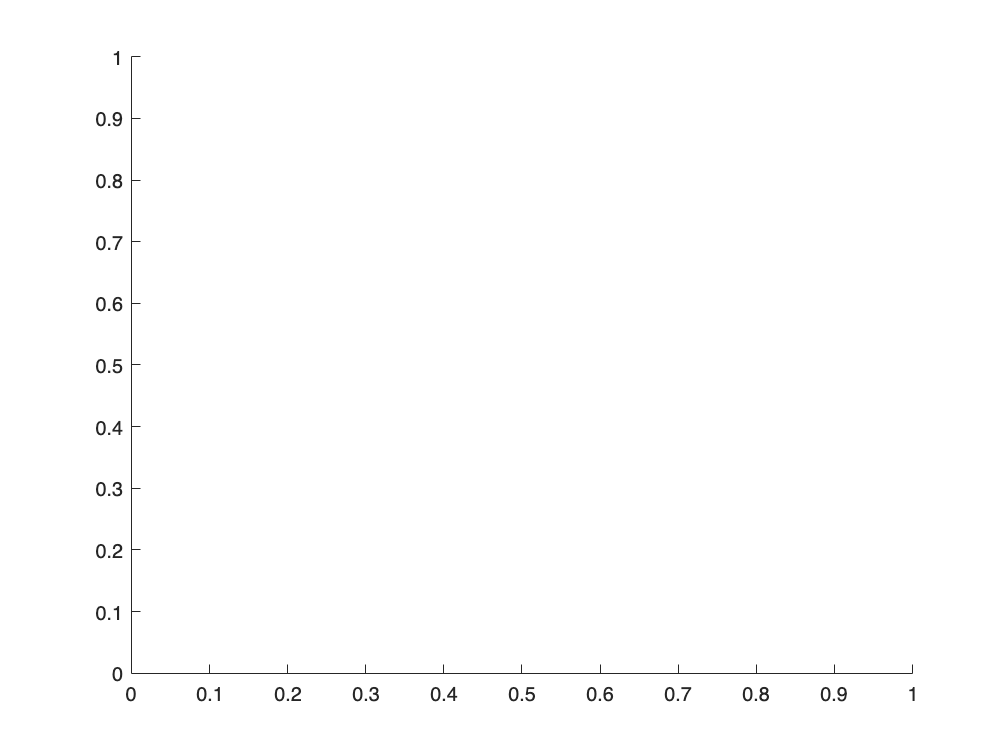

%优化函数
function d = sum_distance_one(x)
% 假设x前半部分是r，后半部分是theta
k = length(x)/2;
r = x(1:k);
theta = x(k+1:end);
ideal_theta = 0:2*pi/9:16*pi/9;
R = ones(1,9)*100;
ideal_x = R.*cos(ideal_theta);
ideal_y = R.*sin(ideal_theta);
% real_x = r.*cos(theta);
% real_y = r.*sin(theta);
real_x = zeros(size(ideal_x));
real_y = zeros(size(ideal_y));
p = 0;
n = 0;
for i = 1:size(real_y)
    % 计算 n 为 i 对 8 取模后加 2
    % [~,n] = min(each_distance(r,theta))
    [~,m] = max(each_distance(r,theta));
    % 循环遍历 m 从 1 到 8
    % for m = 1:8
    % 如果 m 等于 n，则跳过当前迭代
    if rand(1)>0.6||n==1
        n = mod(i, 8) + 2;
    else
        [~,n] = min_distance(r,theta);
    end
    
    if rand(1)>0.6 || p==1
        p = mod(i, 8) + 2;
    else
        [~,p] = second_min(r,theta);
    end
   
    if m == p || m==n
        if rand(1)>0.5
            continue
        else
            m = mod(floor(rand(1)*10),8)+1;
        end
    end

    if m==1
        continue;
    end
    % 计算 pbl3_a1 和 pbl3_a3
    % pbl3_a1 = pi / 2 + theta(m) / 2;
    pbl3_a1 = 20*m-110;
    % pbl3_a3 = theta(n) / 2;
    pbl3_a3 = 30*n;
    pbl3_a2 = pbl3_a1 - pbl3_a3;
    pbl3_a3p = 30*p;
    pbl3_a2p = pbl3_a1 - pbl3_a3p;
    % 调用 a2a3torhotheta 函数计算 R_m 和 rho_m
    
    % [R_m, rho_m] = a2a3torhotheta((pbl3_a1 - pbl3_a3), pbl3_a3, theta(n),R);
    [R_m, rho_m] = four_a2a3toR(r(p),theta(p),r(n),theta(n),pbl3_a2p,pbl3_a2,m)
    % 更新 temp_r 和 theta 的值
    r(m) = R_m;
    theta(m) = rho_m;

end
real_x = r.*cos(theta);
real_y = r.*sin(theta);
d = sum((ideal_y-real_y).^2+(ideal_x-real_x).^2);
end


function stop = plotOptimValues(x, optimValues, state)
stop = false; % 如果你想基于某些条件停止优化过程，可以设置这个变量为true
switch state
    case 'iter'

        disp(['当前迭代次数: ', num2str(optimValues.iteration)]);
        % disp(['当前x的值: ', num2str(x)]);
        n = length(x)/2;
        r_ = x(1:n);
        theta_ = x(n+1:end);
        x_ = r_.*cos(theta_);
        y_ = r_.*sin(theta_);
        scatter(x_,y_);
        % a1_ = t2angle([0,0],[x_,y_],[100,0]);
        % 绘制当前解或其他信息
        % 例如，绘制当前函数值

        % plot(optimValues.iteration, optimValues.fval, 'o');
        % plot(optimValues.iteration, a1_, 'o');
        % 保持图像，以便在同一图上绘制所有点
        axis equal;
        scatter(x_,y_);
        xlabel('x');
        ylabel('y');
        % legend
        drawnow; % 立即更新图形
end
end

%初始值
r = [100 98 112 105 98 112 105 98 112];
theta = [0 40.10 80.21 119.75 159.86 199.96 240.07 280.17 320.28];
x0 = [r,theta];
hold on;

%无条件约束,寻找全局最优解
% 创建一个匿名函数
objFun = @(x) sum_distance_one(x);

% 在optimoptions中设置OutputFcn
options = optimoptions('fminunc', 'Display', 'iter', 'Algorithm', 'quasi-newton', 'OutputFcn', @plotOptimValues);

% 调用fminunc函数
[x, fval] = fminunc(objFun, x0, options);

错误使用 four_a2a3toR
输入参数太多。

出错 global_optimal>sum_distance_one (第 58 行)
    [R_m, rho_m] = four_a2a3toR(r(p),theta(p),r(n),theta(n),pbl3_a2p,pbl3_a2,m)

出错 global_optimal>@(x)sum_distance_one(x) (


% 显示最优解和目标函数值
disp(['最优解: ', num2str(x)]);
disp(['目标函数值: ', num2str(fval)]);